## Load Station Aloha Temperature data

T: temp (°C), t: time, z: depth (m)

clear;clc;close;clf
load HOTS_Temp.mat
nt = length(t);
nz = length(z);

## Remove time average

Td = detrend(T',0)';

Covariance matrix - Last time we computed the covariance matrix as C = 1/(nt-1)*(Td*Td').  Td has dimensions nz by nt, so in this form the covariance is computed summed over time, and C has dimension nz by nz, and the eigenvectors have the dimension time, and the PCs have the dimension space.  For convenience, let's drop the 1/(nt-1), which will not affect the computation of the eigenvectors or PCs (it does affect the eignvalues, but we're only concerned about the percent variance of each mode, which is unaffected by the normalization).

More commonly when the data matrix (Td) has # of rows  > # of columns (in our case nz > nt), the covariance marix is formed as C = Td'*Td.  The eigenvectors then have the smaller dimension, in this case time, and the PCs have the larger space dimension.  

## C2 = Td'*Td  compared to C = Td*Td'

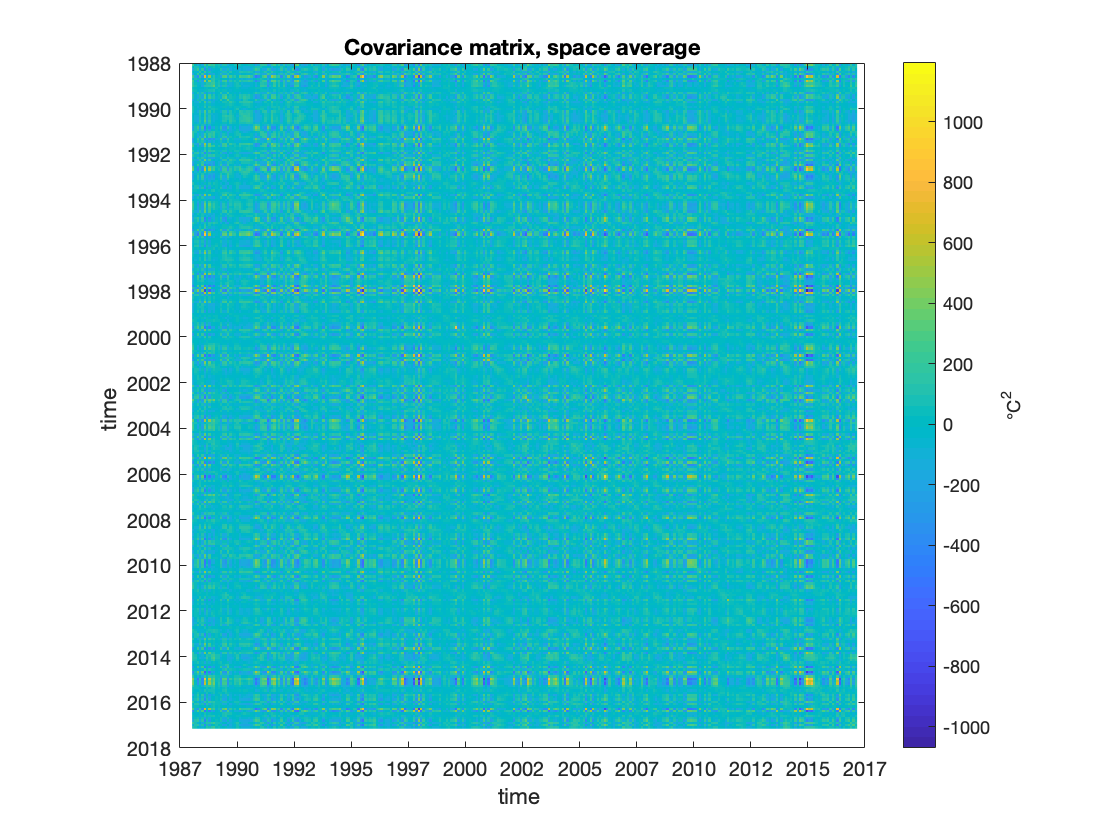

C2 = Td'*Td; % new

figure (1)
clf
imagesc(t,t,C2)
cb = colorbar;
ylabel(cb,'°C^2')
ylabel('time ')
xlabel('time ')
datetick('x')
datetick('y')
title('Covariance matrix, space average')
axis('square')

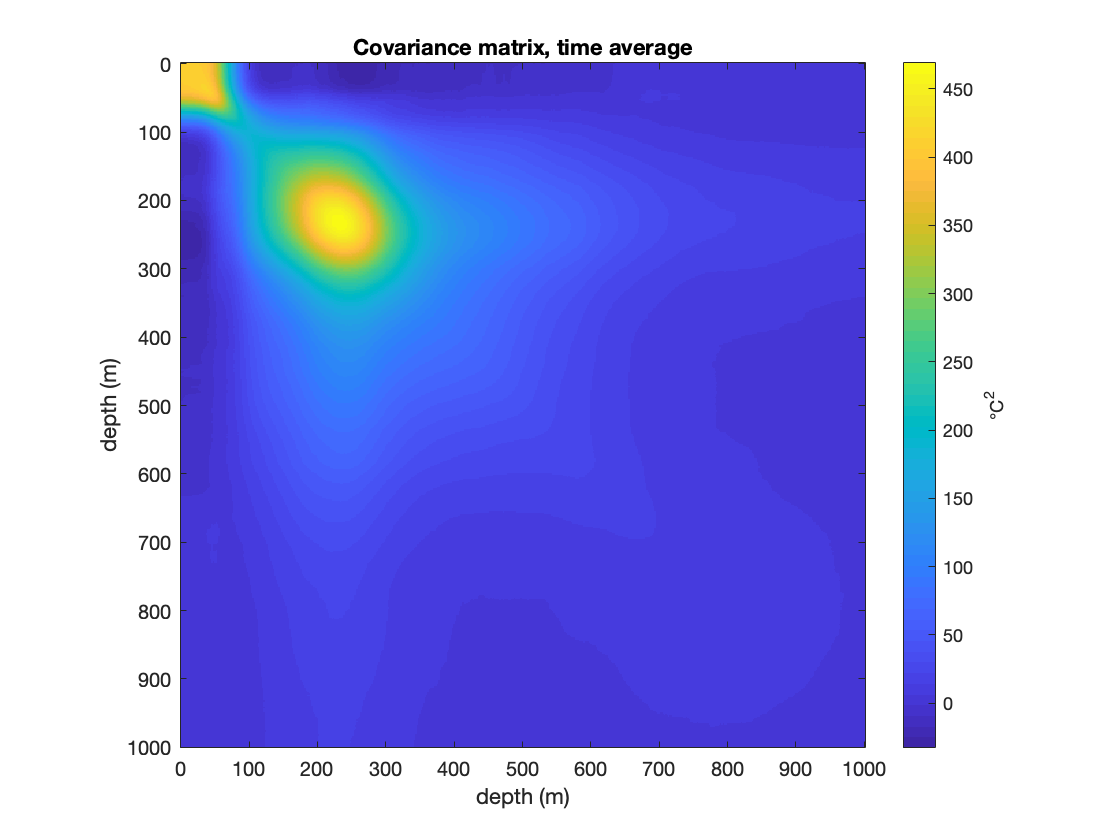

C1 = Td*Td';

figure (2)
clf
imagesc(z,z,C1)
cb = colorbar;
ylabel(cb,'°C^2')
ylabel('depth (m)')
xlabel('depth (m)')
title('Covariance matrix, time average')
axis('square')

## Compute EOF and plot percent variance of each mode using C2

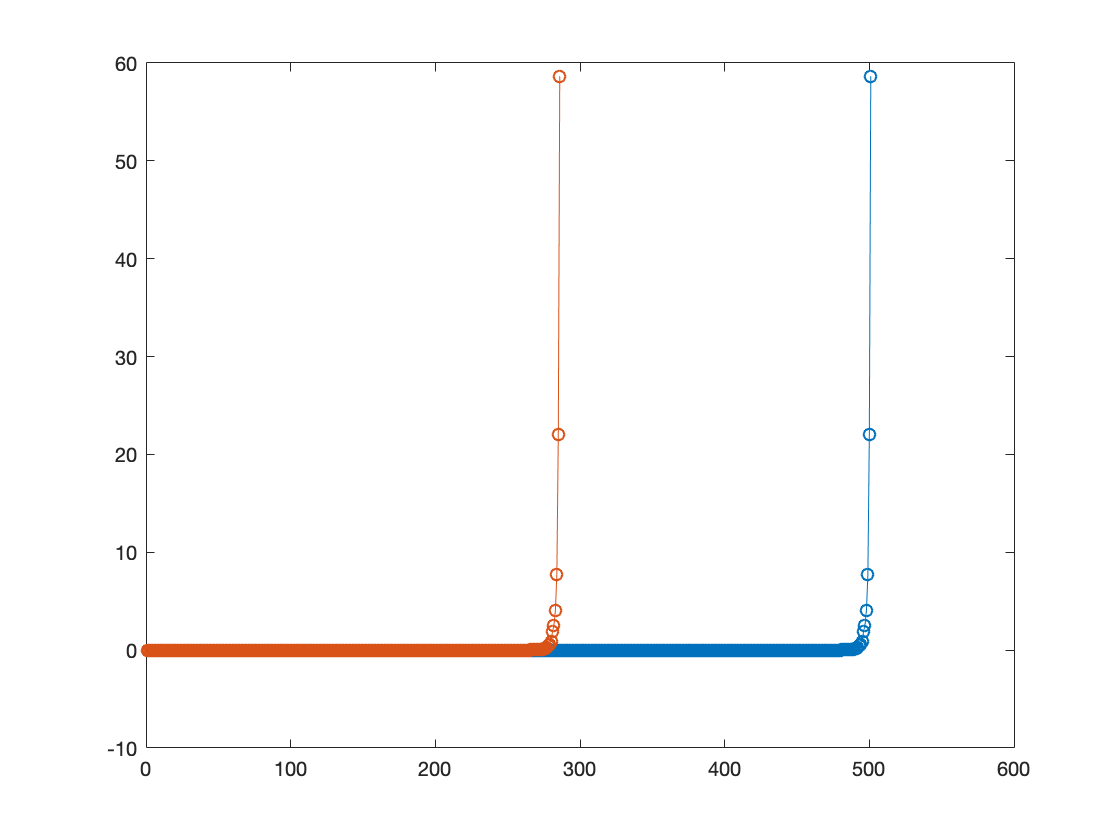

[e2,lambda2] = eig(C2);
[e1,lambda1] = eig(C1);
lambda1 = diag(lambda1);
lambda2 = diag(lambda2);
pvar1 = lambda1/sum(lambda1)*100; % percent variance
pvar2 = lambda2/sum(lambda2)*100; % percent variance
figure (4)
plot(pvar1,'o-');hold on; plot(pvar2,'-o')

## Reverse the order of the modes if necesary

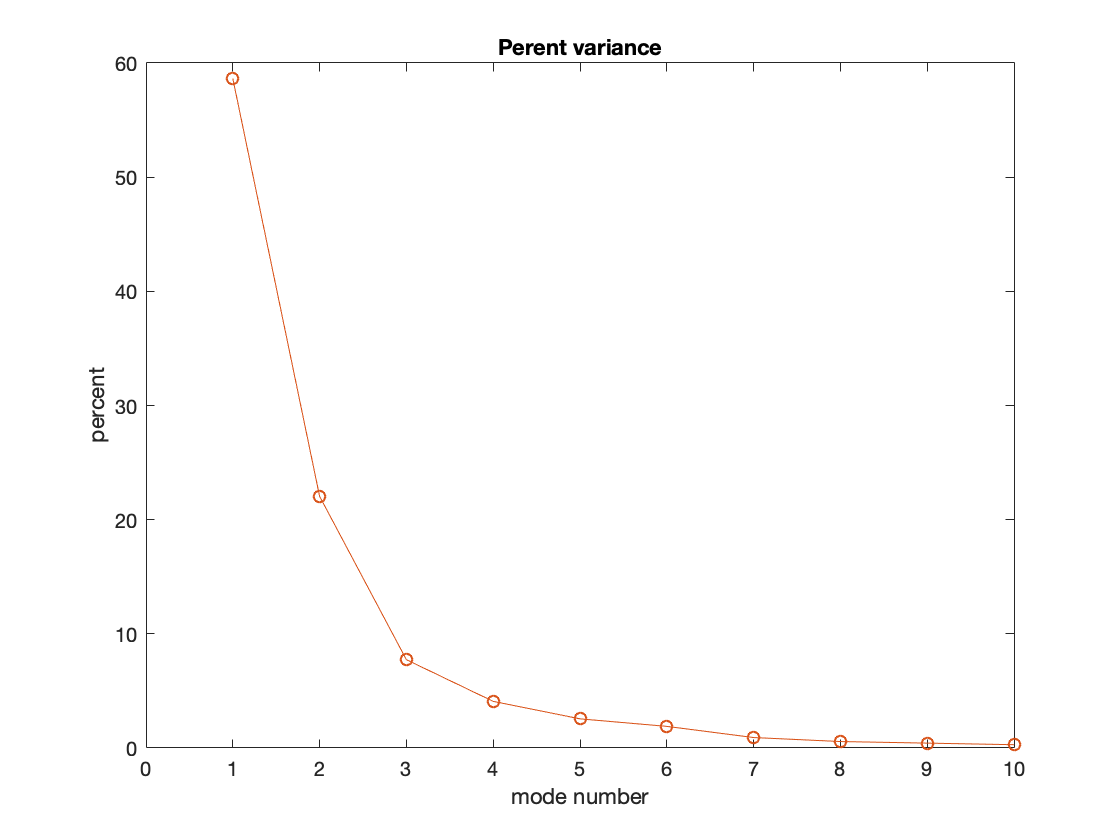

e1 = fliplr(e1); 
lambda1 = flipud(lambda1);
pvar1 = flipud(pvar1);

e2 = fliplr(e2); 
lambda2 = flipud(lambda2);
pvar2 = flipud(pvar2);
clf
plot(pvar1,'o-');hold on;plot(pvar2,'o-')
xlim([0,10])
title('Perent variance')
xlabel('mode number')
ylabel('percent')

## Plot EOFs, now time series

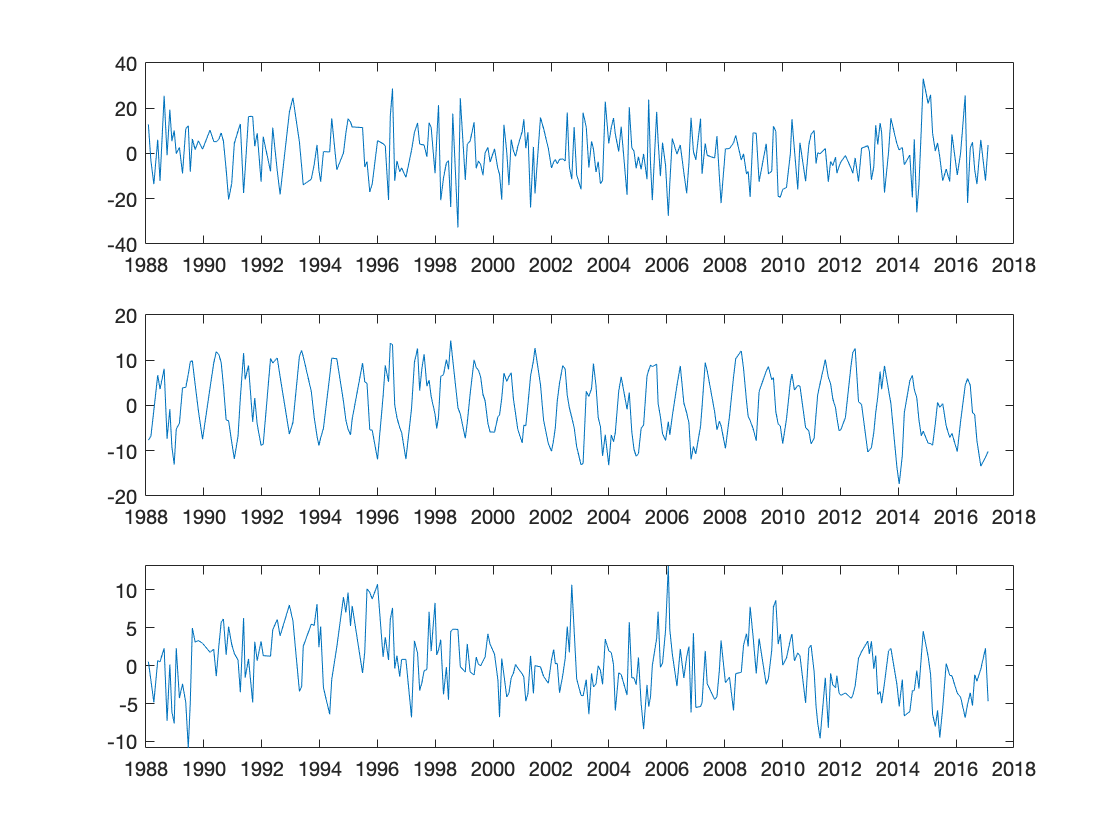

clf
figure(5)
A1 = Td'*e1;
A2 = Td'*e2;
subplot(3,1,1)
plot(t,A1(:,1))
datetick
A1 = Td'*e1;
subplot(3,1,2)
plot(t,A1(:,2))
datetick
A1 = Td'*e1;
subplot(3,1,3)
plot(t,A1(:,3))
datetick

## Plot PCs, now depth profiles.   Compute PCs as A = Td*e;

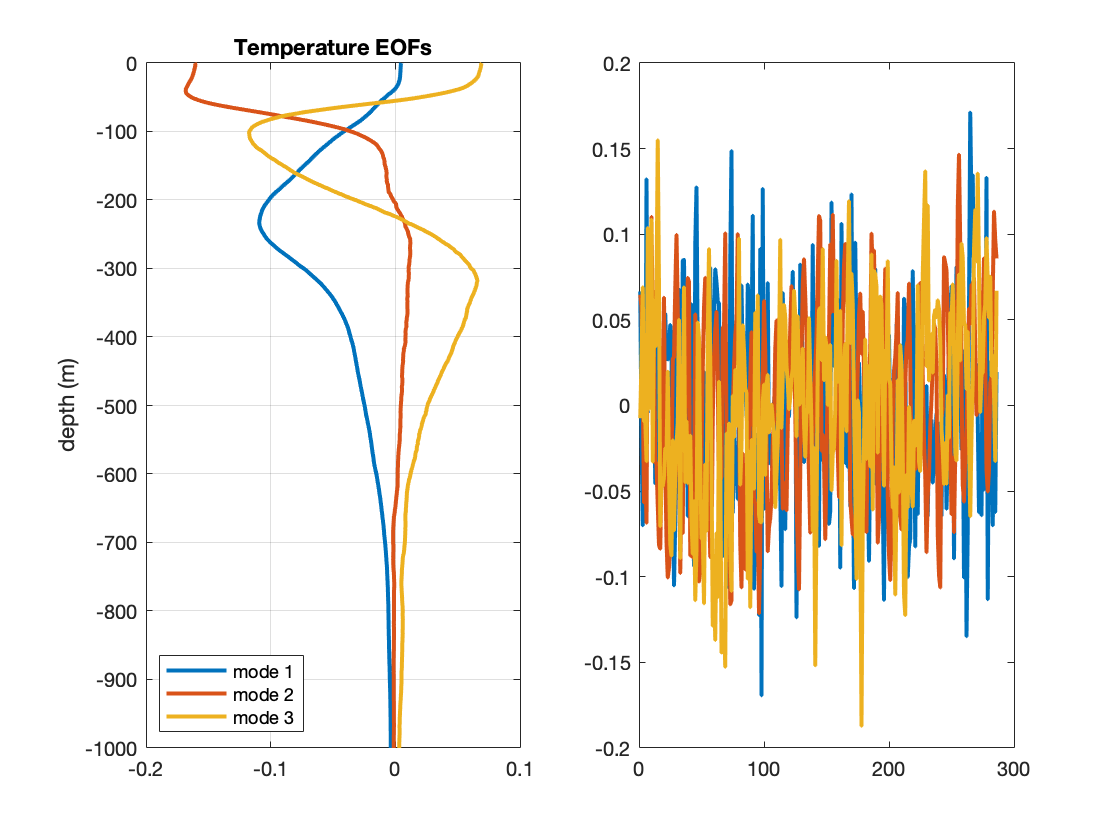

clf
figure(6)
subplot(1,2,1)
plot(e1(:,1:3),-z,'LineWidth',2) % plot eigenvectors  against depth
% last mode, gives us connections in variability between the first two
% modes, first two mdoes explain similar pattern in mixed layer and
% thermocline?
ylabel('depth (m)')
title('Temperature EOFs')
grid on
legend('mode 1','mode 2','mode 3')
legend('location','SouthWest')
subplot(1,2,2)
plot(e2(:,1:3),'LineWidth',2)